## Rendering noise analysis

We illustrate the rendering noise by comparing the amount of noise as a function of the number of rays and the number of bounces.  We do this in two different cases.  The first case illustrates a simple flat surface where the number of bounces will not matter.  The second case illustrates rendering the Cornell Box in which there are inter-reflections.

%% Initialize and check that Docker is configured
ieInit;
if ~piDockerExists, piDockerConfig; end

## Flat surface: pinhole

First sweep out the case of a flat surface and a simple, monochrome sensor.  

The case of a pinhole runs quickly and converges quickly because there is almost no aperture sampling.

rays = [4 64 128 512];
[rn, pn] = piRenderNoise('rays',rays, 'lensname','pinhole');

Read 2 materials.
Read 0 textures.
***Scene parsed.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   1.39
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   3.00
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/c/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.78
Complete render took: 6.48e+00 seconds.*** Rendering time for flatSurface:  6.5 sec ***

exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.84
Render: docker --context render-vista exec -

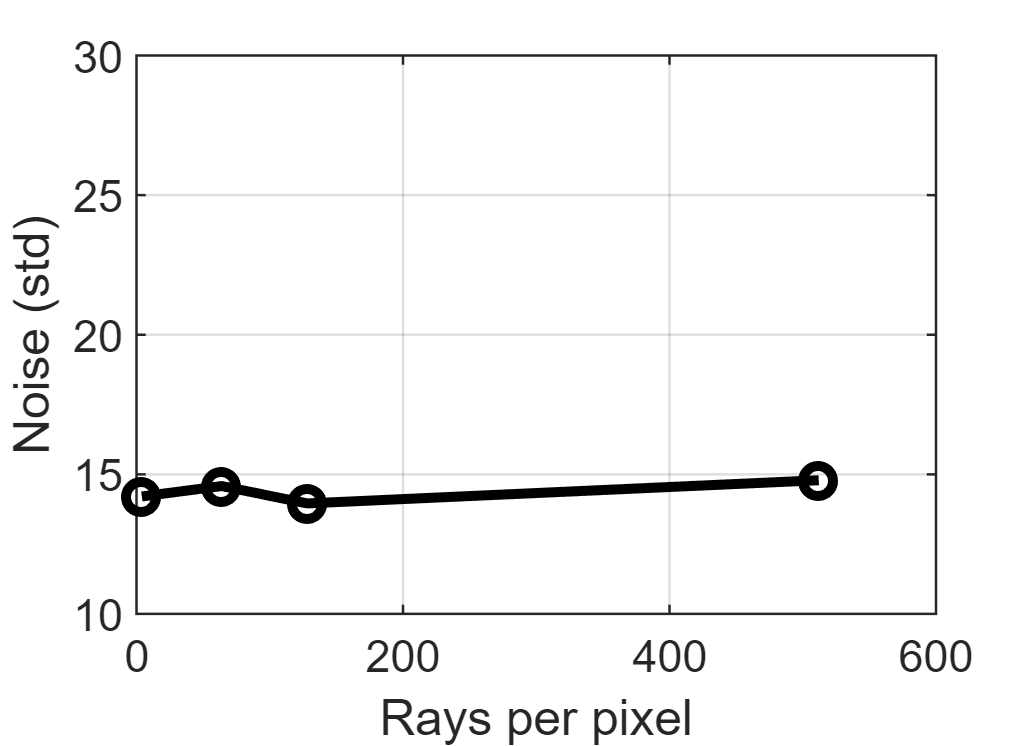


ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise (std)');
ylim([10 30]);

## Flat surface:  lens

The case of a simple double-Gauss lens converges more slowly

rays = [64 128 512 1024];
[rn, pn] = piRenderNoise('rays',rays,'lensname','dgauss.22deg.12.5mm.json');

Read 2 materials.
Read 0 textures.
***Scene parsed.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.88
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   4.87
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/c/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.89
Complete render took: 7.83e+00 seconds.*** Rendering time for flatSurface:  7.8 sec ***

exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.93
Render: docker --context render-vista exec -

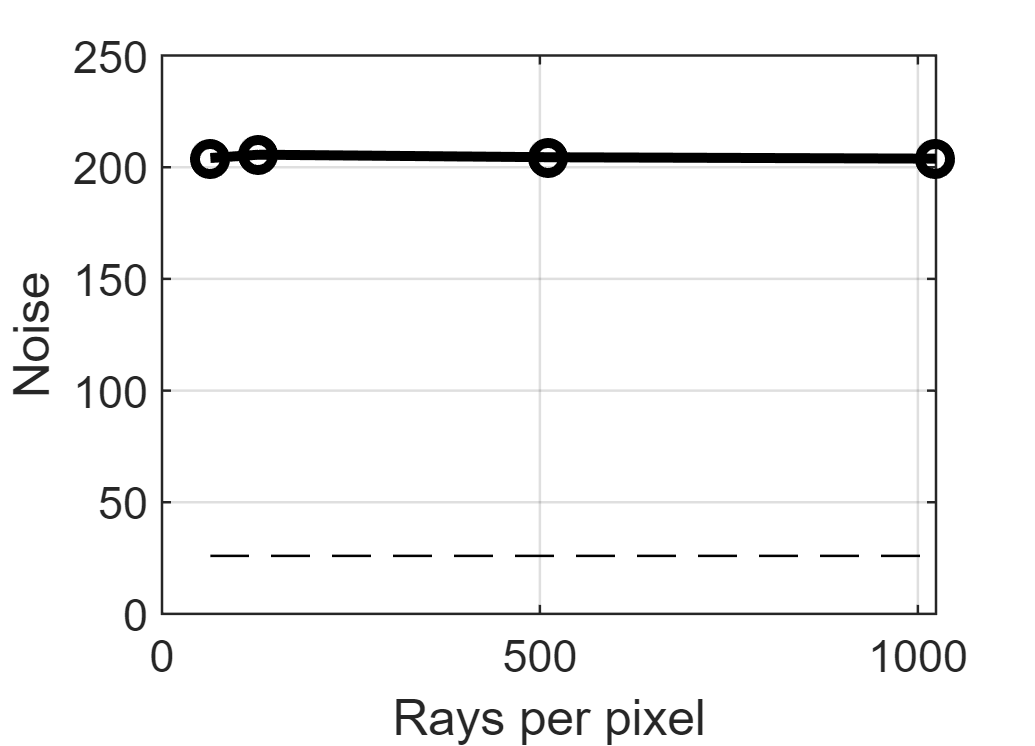


ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise');

## Cornell box:  back surface

The number of bounces becomes relevant for the Cornell box, with its inter-reflections.  We start with the back surface in the middle.  There are not as many inter-reflections there (though some!).  We can try other parts of the scene.

By making a very small film diagonal, we only measure a small part of the image.  But even though it is small, there is probably still some shading that increases the render noise value.

rays = [64 512 1024];
nBounceList = [1 2 4 8];
rnList = zeros(numel(nBounceList), numel(rays));
pnList = zeros(1, numel(nBounceList));

for ii=1:numel(nBounceList)
[rn, pn, idealSensor] = piRenderNoise('rays',rays,...
    'scene name','cornell box reference', ...
    'film diagonal',0.15, ...
    'nbounces',nBounceList(ii));
rnList(ii, :) = rn;
pnList(ii) = pn;
end

Read 10 materials.
Read 0 textures.
***Scene parsed.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/CornellBoxReference/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/CornellBoxReference/
Pushed scene to remote in:   0.84
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/CornellBoxReference && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/CornellBoxReference.exr CornellBoxReference.pbrt"
Successfuly rendered remotely in:   4.62
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/CornellBoxReference/renderings/ /mnt/c/iset/iset3d-v4/local/CornellBoxReference/renderings
Retrieved output in:   0.77
Complete render took: 7.43e+00 seconds.*** Rendering time for CornellBoxReference:  7.4 sec ***

exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/CornellBoxReference/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/CornellBoxReferenc

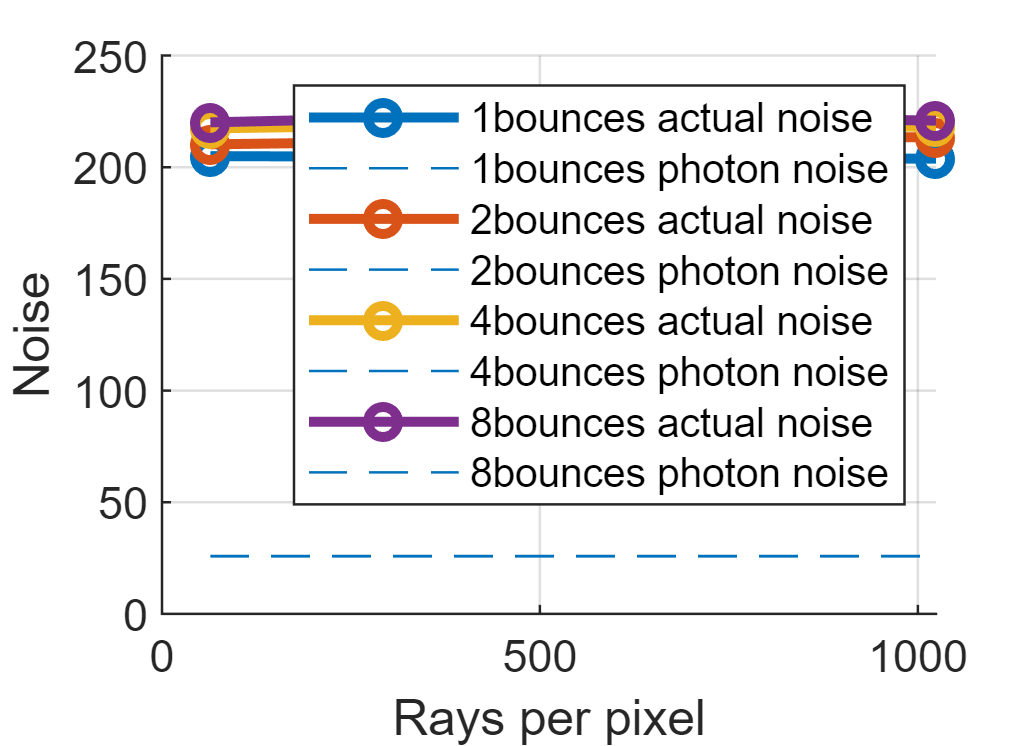


legendName = cell(1, 2 * numel(nBounceList));
ieNewGraphWin;
hold all
for ii=1:numel(nBounceList)
plot(rays, rnList(ii,:), '-o','Linewidth',2);
line([rays(1), rays(end)],[pnList(ii), pnList(ii)],'Linestyle','--');
legendName{2*(ii-1)+1} = [num2str(nBounceList(ii)), 'bounces actual noise'];
legendName{2*ii} = [num2str(nBounceList(ii)), 'bounces photon noise'];

end
grid on; xlabel('Rays per pixel'); ylabel('Noise');
legend(legendName);


%{
ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise');
%}